# Direct Cinematic 3D interactive model of the robot

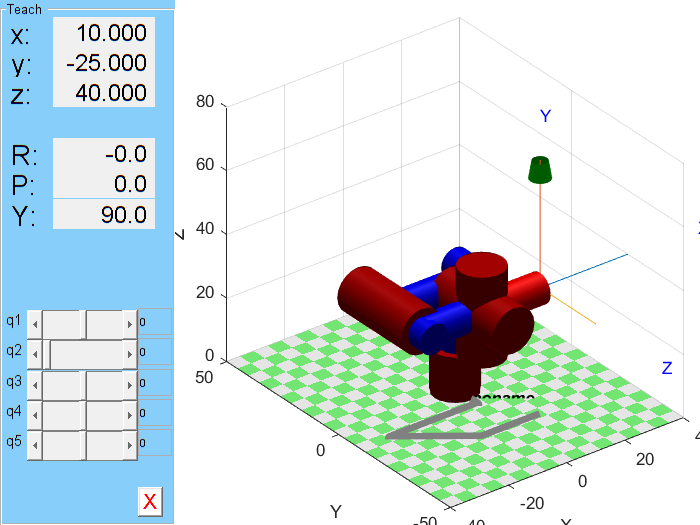

%% Please install first the Peter's Corke toolbox:
%% https://petercorke.com/toolboxes/robotics-toolbox/

clear; close ;clc

 l1=40;
 l2=10;
 l3=15; 
 l4=20;
 l5=20;
 d2=30;

 ws=[-40,40,-50,50,0,80]; % Delimita el workspace de la simulacion

 % D-H Parameters [theta , d , a , alpha , offset]
 % If prismatic: theta=theta, d=0, offset=1
 % If rvolute: theta=0, offset=0
 % Para elegir el offset d o theta, se escribe detras del offset

 L1= Link([0,l1,l2,-pi/2,0,-pi/2]);
 L2= Link([+pi/2,0,0,-pi/2,1,-d2]);
 L2.qlim =[0 d2];
 L3= Link([0,-l3,l4,-pi/2,0,-pi/2]);
 L4= Link([0,0,0,-pi/2,0]);
 L5= Link([0,0,l5,0,0]);

 robot=SerialLink([L1 L2 L3 L4 L5]);
 robot.plot([0,0,0,0,0], 'workspace', ws);
 robot.teach();